# Burst photography example

Burst photograph has become common. Here is an example of combining multiple exposures of the same duration in ISETCam. This case is simple because there is no motion in the scene. For general burst photography, objects (and the camera) move and the full algorithm has to include alignment code.

Wandell, 2019

Livescript conversion, Cardinal, 2020

See also sensorComputeMEV, t_sensorMultipleExposure

ieInit
wbState = ieSessionGet('waitbar');
ieSessionSet('waitbar',false);  % Dealing with a waitbar/Matlab issue.

## Set up the default scene and the oi

We use an HDR scene for maximum effect.

% scene = sceneCreate;
scene = sceneFromFile('Feng_Office-hdrs.mat','multispectral');

Reading multispectral data with mcCOEF.
Saved using svd method


% sceneWindow(scene); sceneSet(scene,'display mode','hdr');
oi = oiCreate; oi = oiCompute(oi,scene);

## Run the sensor simulation

First in auto exposure mode.  Kind of a lousy rendering of the image.

sensor = sensorCreate; 
sensor = sensorSet(sensor,'fov',sceneGet(scene,'fov'),oi);
sensor = sensorCompute(sensor,oi);

Line is (x,y), not row,col.  (1,1) is upper left corner. 

The bright region is the window in the image.

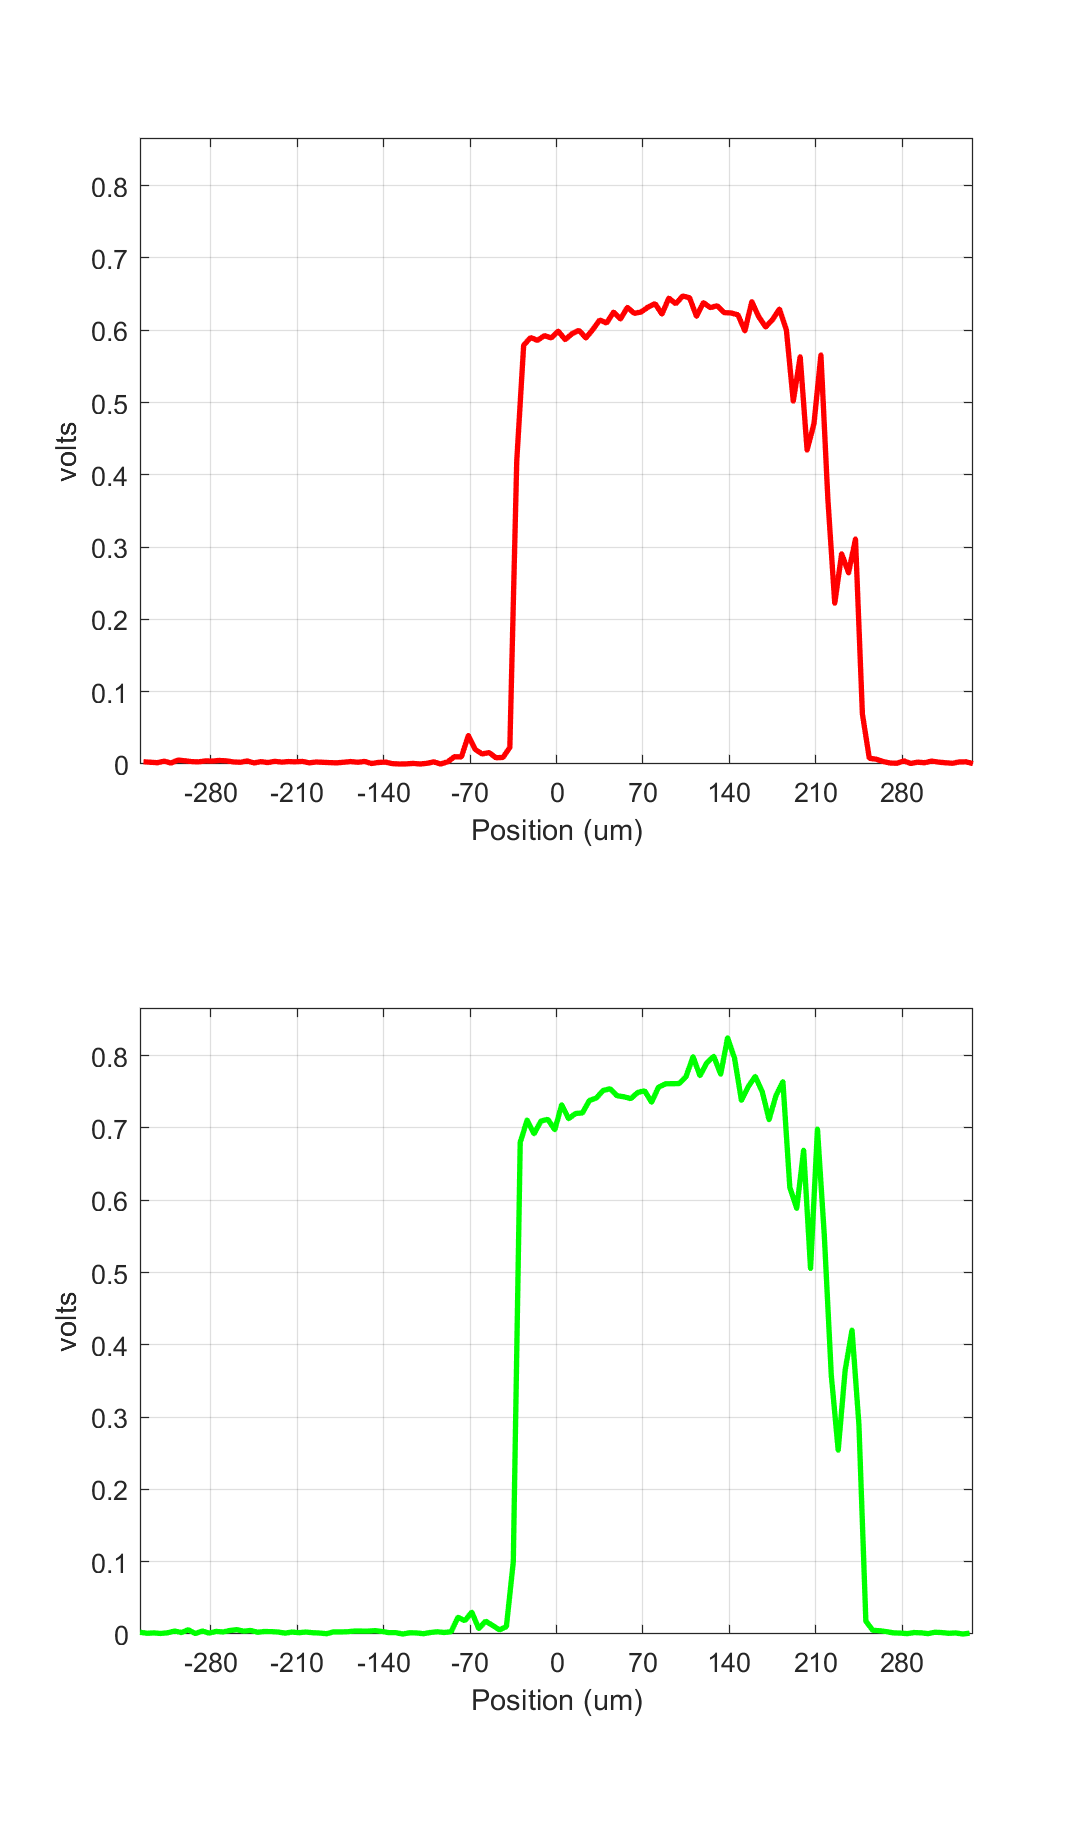

sensorPlot(sensor,'volts hline',[1,55]);

sensor = sensorSet(sensor,'name','Auto exposure');
sensorWindow(sensor);

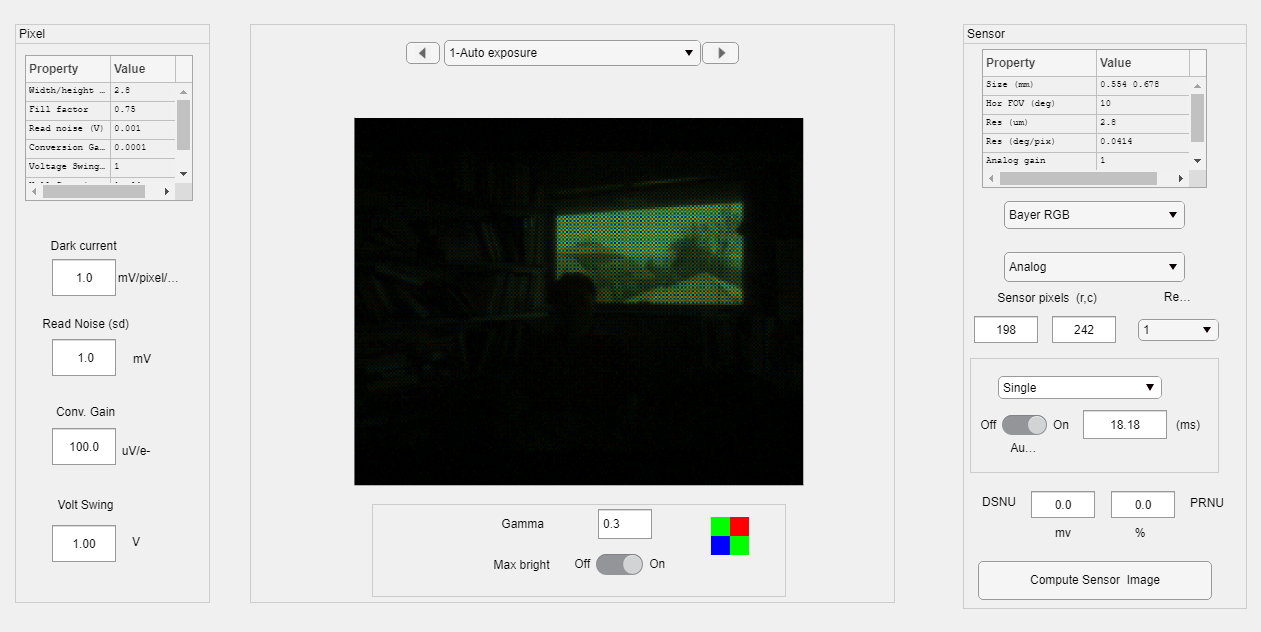

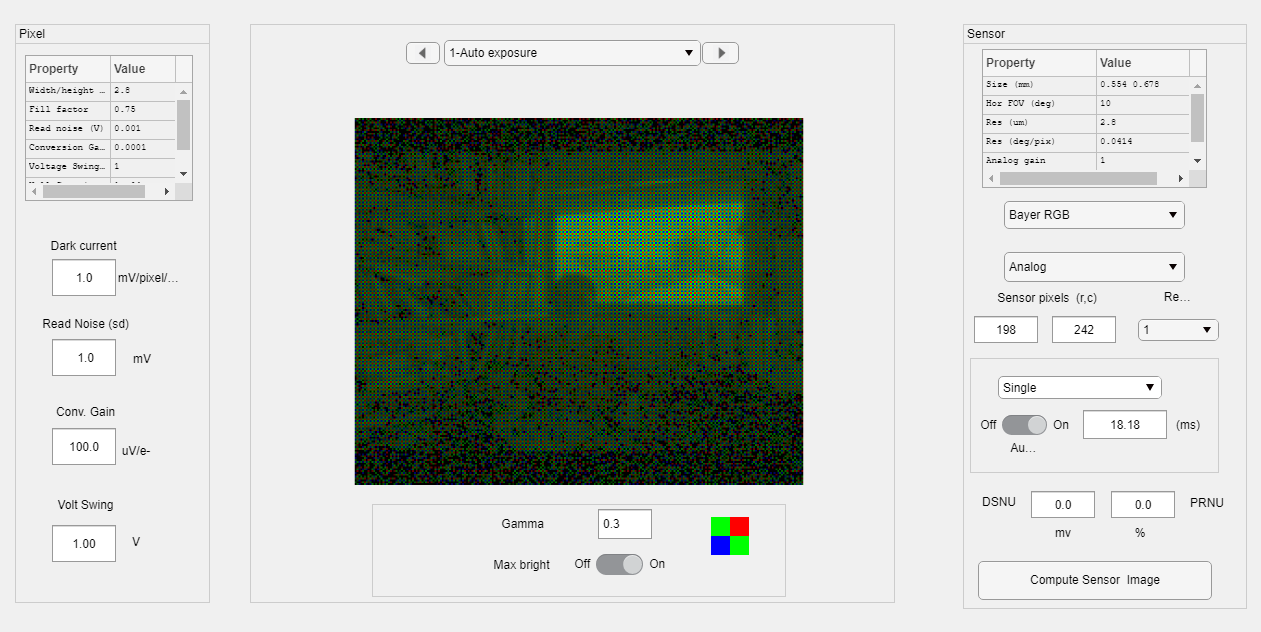

sensorSet(sensor,'gamma',0.3);

## Now operate the sensor in burst mode

We turn off all the sensor noise, but there is still some other remaining noise.

Use the slider to control how many images to take in a burst. Notice the effect of using more or fewer frames on noise.

numImages     = 3

numImages = 3

expTime     = autoExposure(oi,sensor)/numImages; % was fixed at 4, but seems like it should vary in some way
burstTiming = repmat(expTime,1,numImages);

sensor      = sensorSet(sensor,'exp time',burstTiming);
sensorBurst = sensorSet(sensor,'noise flag',2); % the default -- full noise 
sensorBurst = sensorSet(sensorBurst,'name',sprintf('burst-full-noise-%d-frames',numel(burstTiming)));
sensorBurst = sensorCompute(sensorBurst,oi);
sensorBurst = sensorSet(sensorBurst,'exp time',burstTiming(1)); % set back
%sensorWindow(sensorBurst);

Now build a low-noise version of the sensor

sensorBurstLN = sensorSet(sensor,'noise flag',-1); % turn sensor noise off
sensorBurstLN = sensorSet(sensorBurstLN,'name',sprintf('burst-low-noise-%d-frames',numel(burstTiming)));
sensorBurstLN = sensorCompute(sensorBurstLN, oi);
sensorBurstLN = sensorSet(sensorBurstLN,'exp time',burstTiming(1));
% sensorWindow(sensorBurstLN);

Currently we simply average the voltage from each image capture

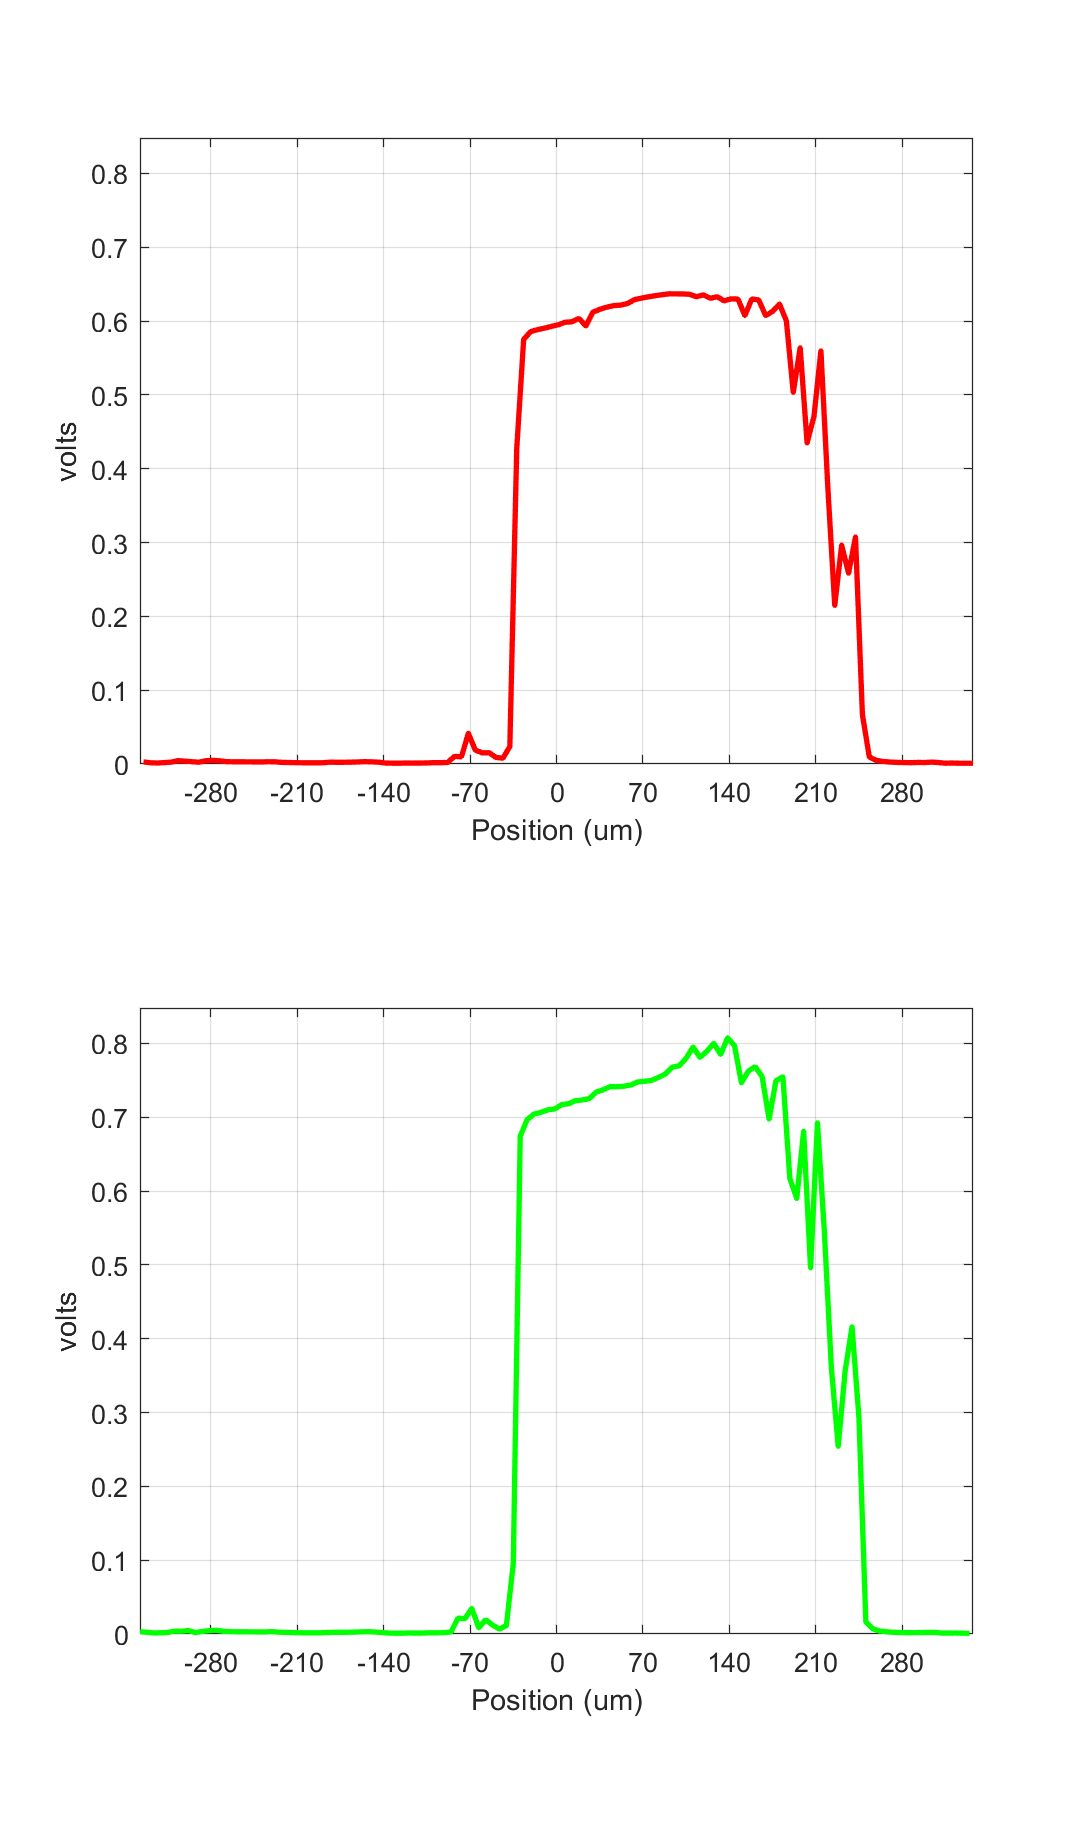

voltsLN = sensorGet(sensorBurstLN,'volts');
voltsLN = mean(voltsLN,3)*numImages;
sensorBurstLN = sensorSet(sensorBurstLN,'volts',voltsLN);
sensorWindow(sensorBurstLN);

% Line is (x,y), not row,col.  (1,1) is upper left corner.
sensorPlot(sensorBurstLN,'volts hline',[1,55]);

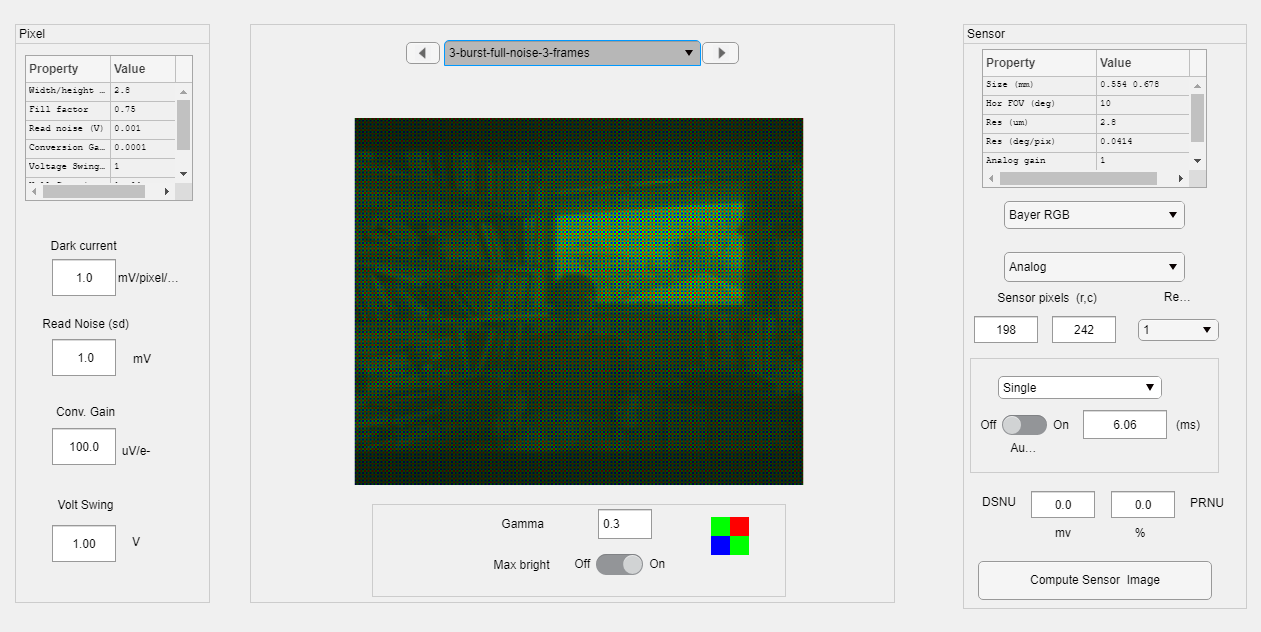

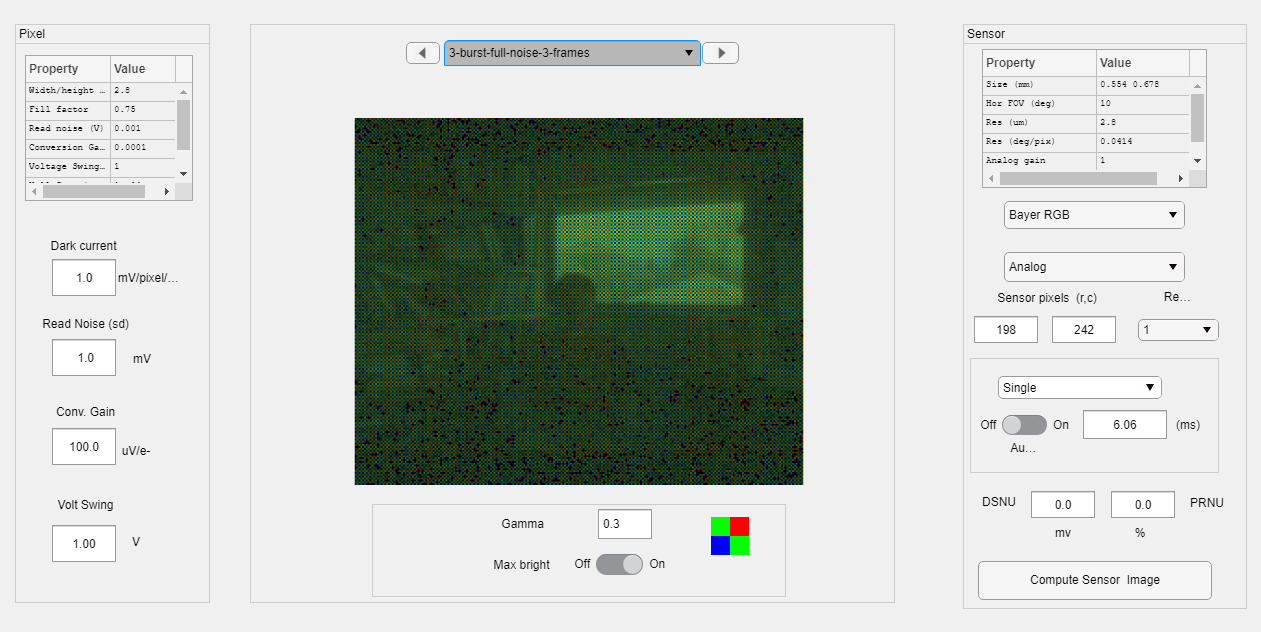


volts = sensorGet(sensorBurst, 'volts');
volts = mean(volts,3)*numImages;
sensorBurst = sensorSet(sensorBurst,'volts',volts);
sensorWindow(sensorBurst);

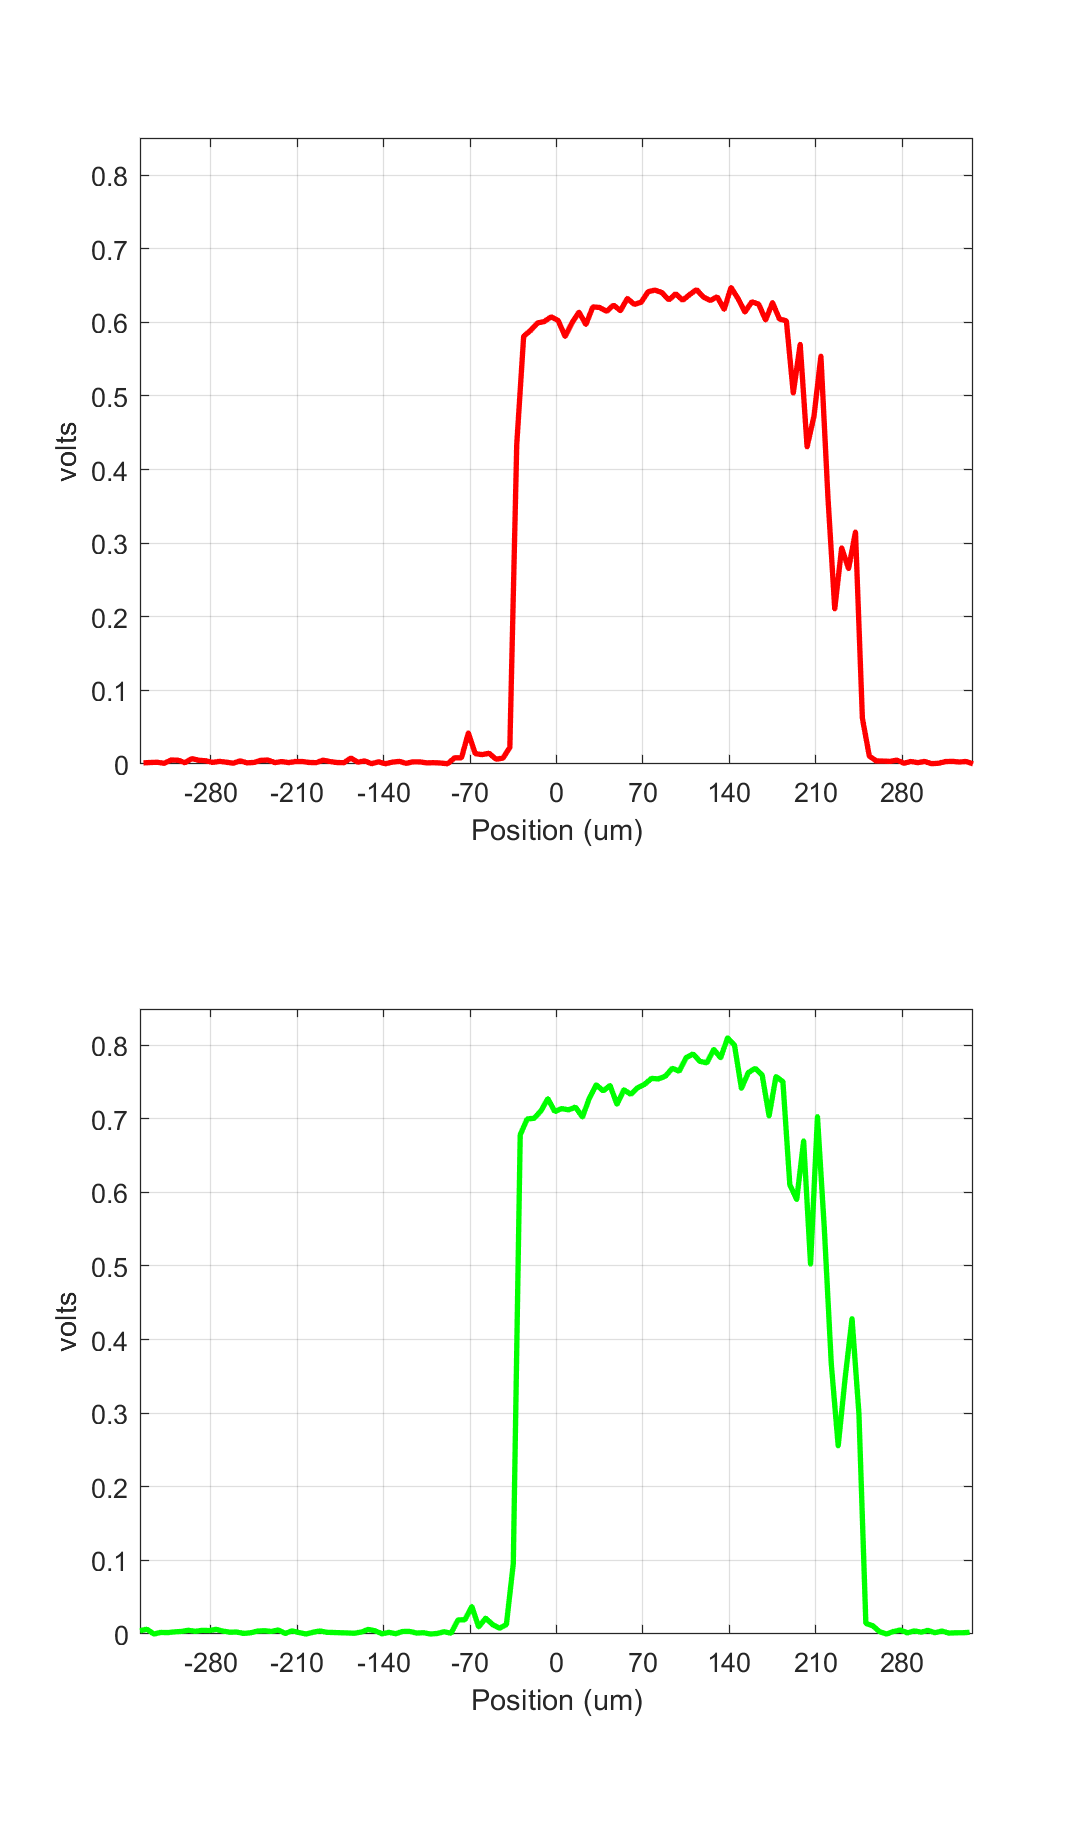


% Line is (x,y), not row,col.  (1,1) is upper left corner.
sensorPlot(sensorBurst,'volts hline',[1,55]);

## Convert through image processing

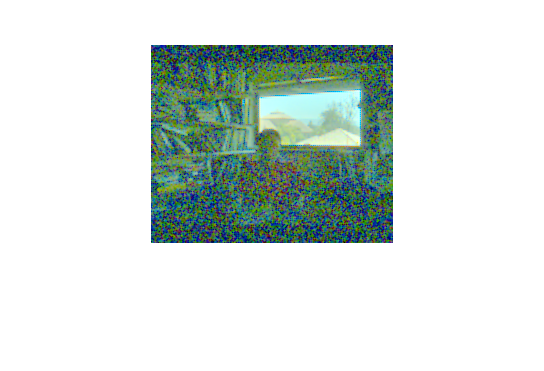

ip  = ipCreate;
ip  = ipCompute(ip,sensorBurstLN);
rgb = ipGet(ip,'srgb');
rgb = hdrRender(rgb);
ieNewGraphWin; imagescRGB(rgb);


ip  = ipCreate;
ip  = ipCompute(ip,sensorBurst);
rgb = ipGet(ip,'srgb');
rgb = hdrRender(rgb);
ieNewGraphWin; imagescRGB(rgb);

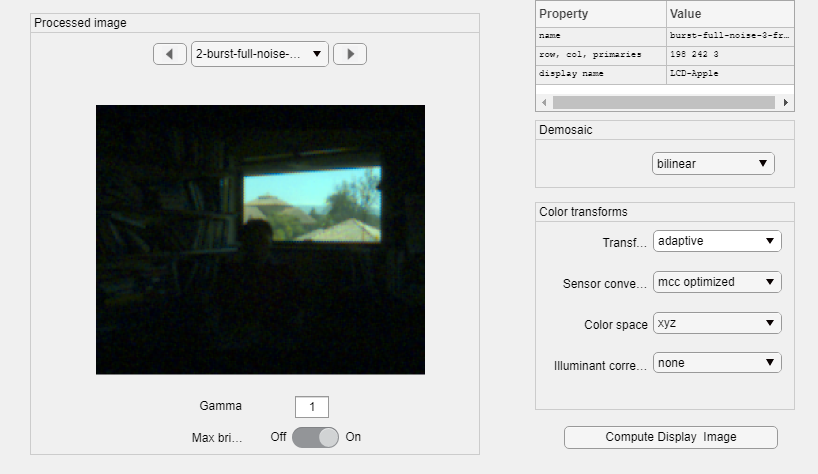


ipWindow(ip);

ieSessionSet('waitbar',wbState);  % Dealing with a waitbar/Matlab issue.